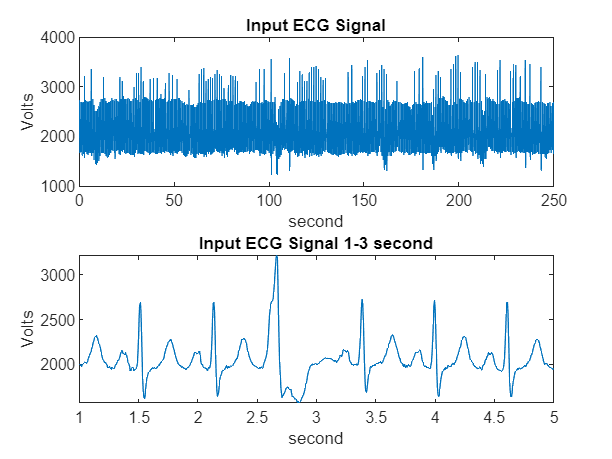

clear all
close all
 
x1 = load('ecgpvc.dat'); % load the ECG signal from the file
fs = 200;              % Sampling rate
N = length (x1);       % Signal length
t = [0:N-1]/fs;        % time index
 
 
figure(1)
subplot(2,1,1)
plot(t,x1)
xlabel('second');ylabel('Volts');title('Input ECG Signal')
subplot(2,1,2)
plot(t(200:1200),x1(200:1200))
xlabel('second');ylabel('Volts');title('Input ECG Signal 1-3 second')
xlim([1 5])

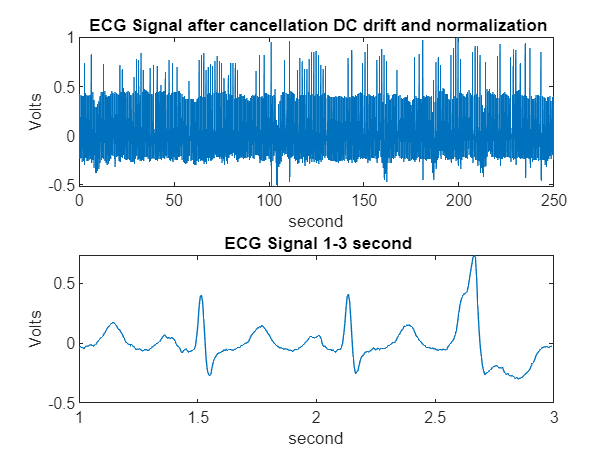


x1 = x1 - mean (x1 );    % cancel DC conponents
x1 = x1/ max( abs(x1 )); % normalize to one
 
figure(2)
subplot(2,1,1)
plot(t,x1)
xlabel('second');ylabel('Volts');title(' ECG Signal after cancellation DC drift and normalization')
subplot(2,1,2)
plot(t(200:600),x1(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])

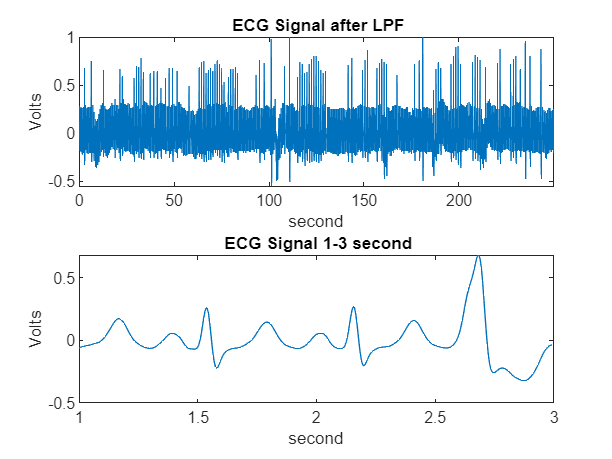


% LPF (1-z^-6)^2/(1-z^-1)^2
b=[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a=[1 -2 1];
 
 
h_LP=filter(b,a,[1 zeros(1,12)]); % transfer function of LPF
 
x2 = conv (x1 ,h_LP);
%x2 = x2 (6+[1: N]); %cancle delay
x2 = x2/ max( abs(x2 )); % normalize , for convenience .
 
figure(3)
subplot(2,1,1)
plot([0:length(x2)-1]/fs,x2)
xlabel('second');ylabel('Volts');title(' ECG Signal after LPF')
xlim([0 max(t)])
subplot(2,1,2)
plot(t(200:600),x2(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])

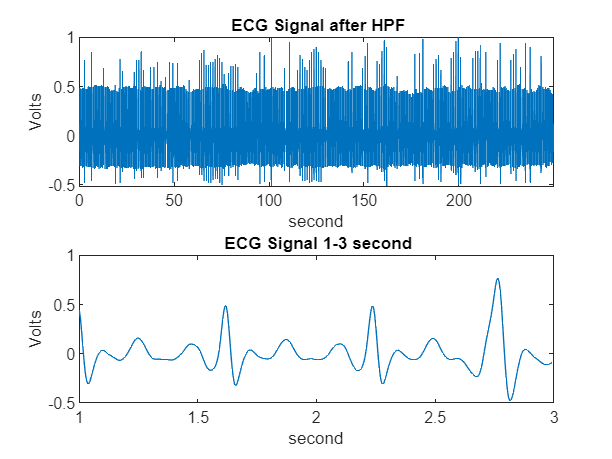


% HPF = Allpass-(Lowpass) = z^-16-[(1-z^-32)/(1-z^-1)]
b = [-1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 32 -32 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a = [1 -1];
 
h_HP=filter(b,a,[1 zeros(1,32)]); % impulse response iof HPF
 
x3 = conv (x2 ,h_HP);
%x3 = x3 (16+[1: N]); %cancle delay
x3 = x3/ max( abs(x3 ));
 
figure(4)
subplot(2,1,1)
plot([0:length(x3)-1]/fs,x3)
xlabel('second');ylabel('Volts');title(' ECG Signal after HPF')
xlim([0 max(t)])
subplot(2,1,2)
plot(t(200:600),x3(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])

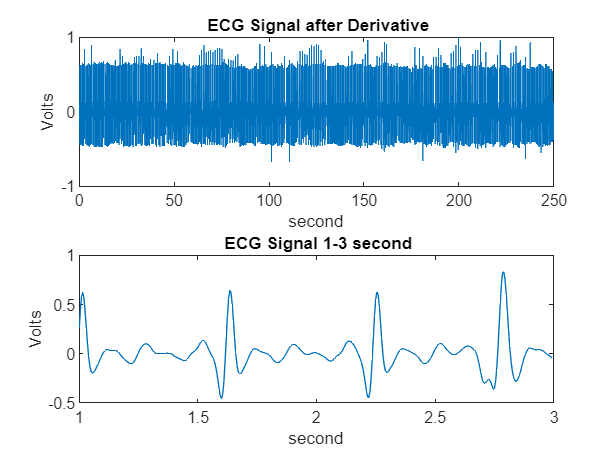


% Make impulse response
h = [-1 -2 0 2 1]/8;
% Apply filter
x4 = conv (x3 ,h);
x4 = x4 (2+[1: N]);
x4 = x4/ max( abs(x4 ));
 
figure(5)
subplot(2,1,1)
plot([0:length(x4)-1]/fs,x4)
xlabel('second');ylabel('Volts');title(' ECG Signal after Derivative')
subplot(2,1,2)
plot(t(200:600),x4(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])

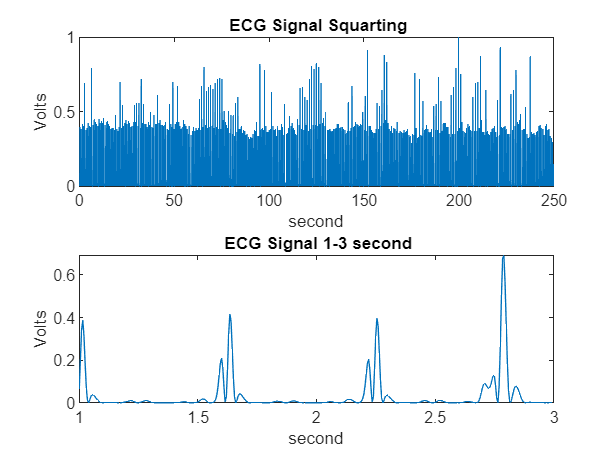


x5 = x4 .^2;
x5 = x5/ max( abs(x5 ));
figure(6)
subplot(2,1,1)
plot([0:length(x5)-1]/fs,x5)
xlabel('second');ylabel('Volts');title(' ECG Signal Squarting')
subplot(2,1,2)
plot(t(200:600),x5(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])

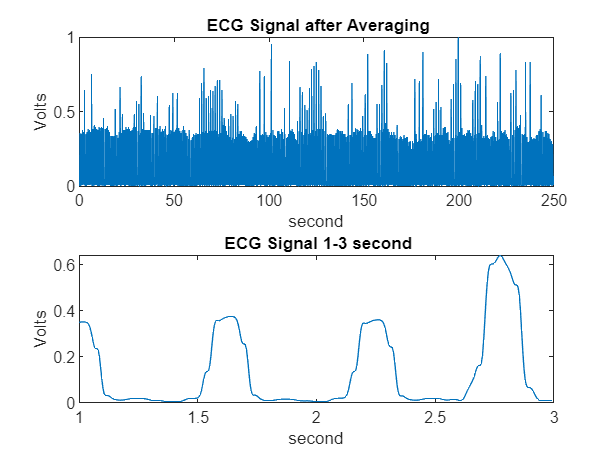



% Make impulse response
h = ones (1 ,31)/31;
Delay = 15; % Delay in samples
 
% Apply filter
x6 = conv (x5 ,h);
x6 = x6 (15+[1: N]);
x6 = x6/ max( abs(x6 ));
 
figure(7)
subplot(2,1,1)
plot([0:length(x6)-1]/fs,x6)
xlabel('second');ylabel('Volts');title(' ECG Signal after Averaging')
subplot(2,1,2)
plot(t(200:600),x6(200:600))
xlabel('second');ylabel('Volts');title(' ECG Signal 1-3 second')
xlim([1 3])


figure(7)
subplot(2,1,1)

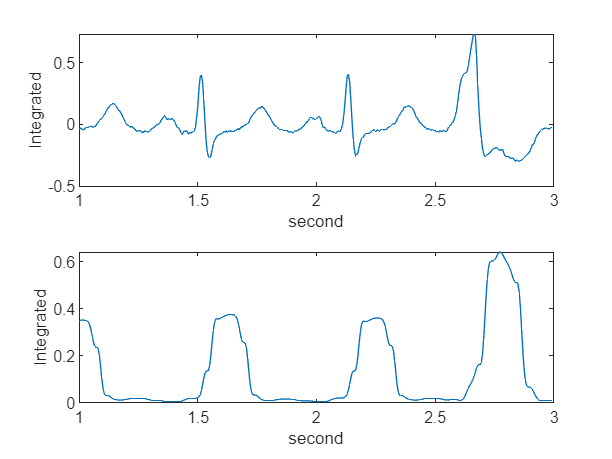

max_h = max(x6);
thresh = mean (x6 );
poss_reg =(x6>thresh*max_h)';
 
figure (8)
subplot(2,1,1)
hold on
plot (t(200:600),x1(200:600)/max(x1))
box on
xlabel('second');ylabel('Integrated')
xlim([1 3])
 
subplot(2,1,2)
plot (t(200:600),x6(200:600)/max(x6))
xlabel('second');ylabel('Integrated')
xlim([1 3])

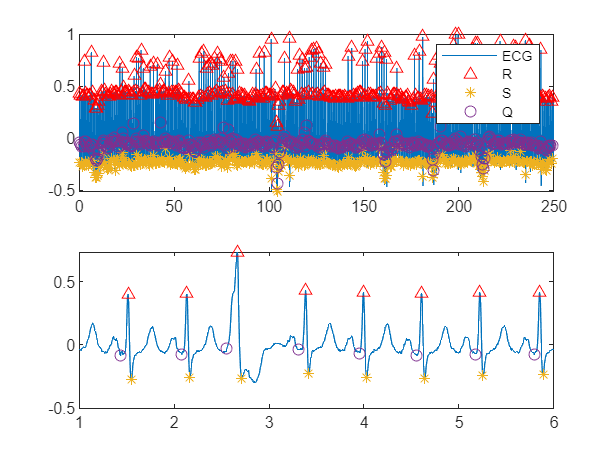

 
left = find(diff([0 poss_reg])==1);
right = find(diff([poss_reg 0])==-1);
 
left=left-(6+16);  % cancle delay because of LP and HP
right=right-(6+16);% cancle delay because of LP and HP
 
for i=1:length(left)
    [R_value(i) R_loc(i)] = max( x1(left(i):right(i)) );
    R_loc(i) = R_loc(i)-1+left(i); % add offset
 
    [Q_value(i) Q_loc(i)] = min( x1(left(i):R_loc(i)) );
    Q_loc(i) = Q_loc(i)-1+left(i); % add offset
 
    [S_value(i) S_loc(i)] = min( x1(left(i):right(i)) );
    S_loc(i) = S_loc(i)-1+left(i); % add offset
 
end
 
% there is no selective wave
Q_loc=Q_loc(find(Q_loc~=0));
R_loc=R_loc(find(R_loc~=0));
S_loc=S_loc(find(S_loc~=0));
 
figure
subplot(2,1,1)
title('ECG Signal with R points');
plot (t,x1/max(x1) , t(R_loc) ,R_value , 'r^', t(S_loc) ,S_value, '*',t(Q_loc) , Q_value, 'o');
legend('ECG','R','S','Q');
subplot(2,1,2)
plot (t,x1/max(x1) , t(R_loc) ,R_value , 'r^', t(S_loc) ,S_value, '*',t(Q_loc) , Q_value, 'o');
xlim([1 6])

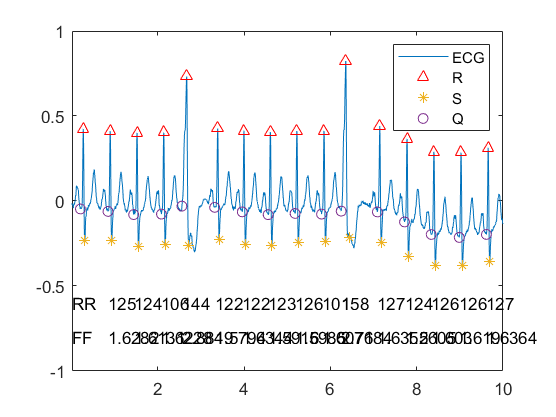



for i=1:length(Q_loc)
    sig=x1(Q_loc(i):Q_loc(i)+80);
    sig_d=diff(sig);
    var1=var(sig);
    var2=var(sig_d);
    var2d=var(diff(sig_d));
    Mx=sqrt(var2/var1);
    Mxd=sqrt(var2d/var2);
    ff(i)= Mxd/Mx;
end


RR=[diff(R_loc) 0];
figure;title('ECG signal with R points');
ylabel('ECG');xlabel('Time in seconds');
plot(t,x1,t(R_loc),R_value,'r^',t(S_loc),S_value,'*',t(Q_loc),Q_value,'o');
axis([0.005 10.005 -1 1]);
legend('ECG','R','S','Q');
end1=find(Q_loc<10.005*fs,1,'last');
r=-0.6;
f=-0.8;
text(t(Q_loc(1)-40),r,'RR ');
text(t(Q_loc(1)-40),f,'FF ');
for j=2:end1
    text(t(Q_loc(j)),r,num2str(RR(j)));
    text(t(Q_loc(j)),f,num2str(ff(j)));
end

p1=find(RR>=135);
p2=find(RR<135);
pvc_RR=RR(p1);
pvc_FF=ff(p1);
normal_RR=RR(p2);
normal_FF=ff(p2)

normal_FF =     1.6066    1.6282    1.6131    1.6228    1.5794    1.6344    1.5916    1.5985    1.6071    1.6352    1.5605    1.6030    1.6190    1.6364    1.6455    1.6376    1.6263    1.5939    1.6313    1.7095    1.6048    1.6402    1.6550    1.6339    1.6953    1.7023    1.7149    2.3801    2.0909    1.6816    1.7265    2.8082    1.7136    1.6471    1.6221    1.6800    1.5955    1.5781    1.6035    1.6365    1.6271    1.6353    1.6245    1.6246    1.7697    3.0848    1.7002    1.6331    1.6498    1.6492



fprintf(['Normal Beats\ncount\t\t\t\t\t=%3.4g \nMean\t\t\t\t RR=%3.4g\t FF=%3.4g\n' 'Standard deviation RR=%3.4g\t FF=%3.4g\n'],length(normal_RR),mean(normal_RR),mean(normal_FF),std(normal_RR),std(normal_FF));

Normal Beats
count					=304 
Mean				 RR=116.3	 FF=1.768
Standard deviation RR=15.97	 FF=0.308


fprintf(['PVC Beats\ncount\t\t\t\t\t=%3.4g \nMean\t\t\t\t RR=%3.4g\t FF=%3.4g\n' 'Standard deviation RR=%3.4g\t FF=%3.4g\n'],length(pvc_RR),mean(pvc_RR),mean(pvc_FF),std(pvc_RR),std(pvc_FF));

PVC Beats
count					= 95 
Mean				 RR=152.3	 FF=2.87
Standard deviation RR=13.1	 FF=0.5899
